cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

cd("../data-engineering")
load("../../temp-data/participant_list.mat")
cd(fileparts(matlab.desktop.editor.getActiveFilename))

Compute <Insert Name> metric and make repeated measure tables.

metric_type = "trmse";
metric_task = "none";
y = compute_performance_table(participant_array, metric_type, metric_task);

### Data Visualizer

y_between = y
w_task = [repmat("Machine Learning", 18,1); repmat("Human Learning", 18,1); repmat("Co-Adaptive Learning", 18, 1)];
w_gesture = repmat([repmat("Co-Activation", 9,1); repmat("Differentiation", 9,1)], 3,1);

Participant 01: P05
	Condition: par
		Task: ml
			Trial 01	Co-Activation:0.429	 Differentiation:0.144
			Trial 02	Co-Activation:0.470	 Differentiation:0.252
			Trial 03	Co-Activation:0.470	 Differentiation:0.287
			Trial 04	Co-Activation:0.417	 Differentiation:0.329
			Trial 05	Co-Activation:0.418	 Differentiation:0.315
			Trial 06	Co-Activation:0.457	 Differentiation:0.172
			Trial 07	Co-Activation:0.394	 Differentiation:0.231
			Trial 08	Co-Activation:0.385	 Differentiation:0.147
			Trial 09	Co-Activation:0.343	 Differentiation:0.285
		Task: hl
			Trial 01	Co-Activation:0.444	 Differentiation:0.110
			Trial 02	Co-Activation:0.322	 Differentiation:0.112
			Trial 03	Co-Activation:0.319	 Differentiation:0.144
			Trial 04	Co-Activation:0.245	 Differentiation:0.120
			Trial 05	Co-Activation:0.246	 Differentiation:0.179
			Trial 06	Co-Activation:0.274	 Differentiation:0.045
			Trial 07	Co-Activation:0.273	 Differentiation:0.057
			Trial 08	Co-Activation:0.380	 Differentiation:0.140
			Tria

w_trial = repmat([1:9]', 6,1);
y_within = table(w_task, w_gesture, w_trial)

### DATA VIZ (RAW)

tlo = tiledlayout('flow');

y_between = 12×55 table
    b_condition      y_1        y_2        y_3        y_4        y_5        y_6        y_7        y_8        y_9        y_10        y_11        y_12       y_13        y_14       y_15       y_16       y_17       y_18       y_19       y_20       y_21       y_22       y_23       y_24       y_25       y_26       y_27       y_28       y_29       y_30        y_31       y_32        y_33        

fontsize(tlo, 20, "points")
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = y_between(y_between.b_condition==cond,2:end);

y_within = 54×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Co-Activation"         5   
    "Machine Learning"    "Co-Activation"         6   
    "Machine Learning"    "Co-Activation"         7   
    "Machine Learning"    "Co-Activation"         8   
    "Machine Learning"    "Co-Activation"         9   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Machine Learning"    "Differentiation"       

    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10 )
        plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        xticks(1:9)
        yticks(0:0.2:0.8)
    end
end
legend_handle = legend(["Co-Activation", "", "Differential Activation"], "Location","eastoutside");
title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim([0, 0.8])
xlim([0 10])
title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)

### DATA VIZ (SEM)

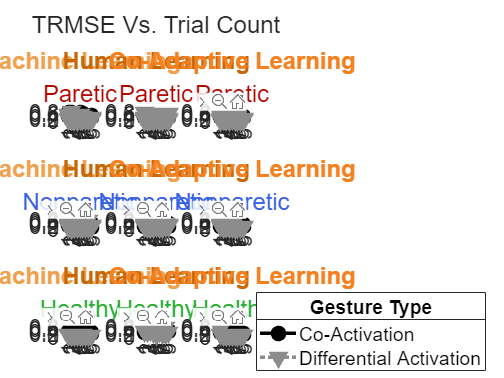

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
ax_handle_list = [];
trials = (1:9)';
for cond = ["par", "xpar", "hlt"]
    y_cond = y_between(y_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]

        y_coact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Differentiation"));
        y_coact_means = mean(y_coact);
        y_diffact_means = mean(y_diffact);
        y_coact_95ci = std(y_coact{:,:})./sqrt(size(y_coact, 1))*1.96;
        y_diffact_95ci = std(y_diffact{:,:})./sqrt(size(y_diffact, 1))*1.96;
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        scatter(trials, y_coact{:,:}', 50, 'black', 'filled', 'o', 'MarkerFaceAlpha', 0.20)
        scatter(trials, y_diffact{:,:}', 50, 'black', 'filled', 'v', 'MarkerFaceAlpha', 0.20)
        errorbar(trials, y_coact_means{:,:}, y_coact_95ci, '-ok', 'MarkerSize',10, 'MarkerFaceColor','black', 'LineWidth',3, 'MarkerEdgeColor','black')
        errorbar(trials, y_diffact_means{:,:}, y_diffact_95ci, ':vk', 'MarkerSize',10, 'MarkerFaceColor','black', 'LineWidth',3, 'MarkerEdgeColor','black')
        hold off
        title([upper(cond), task])
        xticks(1:9)
    end
end
legend(["Co-Activation", "Differential Activation"])
linkaxes(ax_handle_list, 'xy')
ylim([0, 1])
xlim([0 10])
title(tlo, upper(metric_type))
set(ax_handle_list, 'FontSize', 18)

rm = fitrm(y_between, 'y_1-y_54~b_condition', "WithinDesign",y_within)

ranova(rm, "WithinModel", "w_task + w_trial + w_gesture + w_trial*w_task")

### Individual Data Plotter

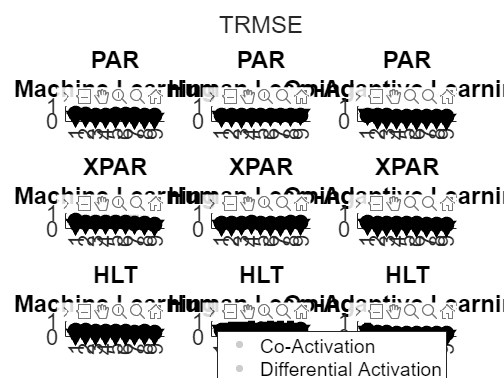

cond_label = "par";
task_label = "ml";
p_handle = participant_array(2);
input_ttbl = p_handle.cond_dict(cond_label).task_dict{task_label}.data_ttbl;
tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
ax_list = [];

for t = 1:9
    trial_label = sprintf("Trial %02d", t);

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [12×55 table]
         ResponseNames: {1×54 cell}
    BetweenFactorNames: {'b_condition'}
          BetweenModel: '1 + b_condition'

   Within Subjects:
          WithinDesign: [54×3 table]
     WithinFactorNames: {'w_task'  'w_gesture'  'w_trial'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [3×54 table]
            Covariance: [54×54 table]


    trial_ttbl = extract_segment(input_ttbl, trial_label, task_label);
    trmse_coact = compute_gesture_metric(trial_ttbl, "trmse", "Co-Activation");

ans = 15×8 table
                                   SumSq      DF     MeanSq        F          pValue       pValueGG      pValueHF      pValueLB 
                                  ________    __    ________    ________    __________    __________    __________    __________

    (Intercept)                      15.41     1       15.41      34.132    0.00024613    0.00024613    0.00024613    0.00024613
    b_condition                   0.086338     2    0.043169    0.095613       0.90973       0.90973       0.90973       0.90973
    Error                           4.0635     9      0.4515                                                                    
    (I

    trmse_diffact = compute_gesture_metric(trial_ttbl, "trmse", "Differentiation");
    ax = nexttile;
    ax_list = [ax_list, ax];
    title(trial_label)
    subtitle(sprintf("Co-Act:%.3f\t Diff Act:%.3f", trmse_coact, trmse_diffact))
    hold on
    plot(trial_ttbl.Time, trial_ttbl.("Targets"), "LineWidth", 3, "LineStyle", ":")
    ax.ColorOrderIndex = 1;
    plot(trial_ttbl.Time, trial_ttbl.("Kalman"), "LineWidth", 3)
    yline([-0.1, 0.1]+0.5, 'r--')
    yline([-0.1, 0.1]+0.0, 'k--')
    hold off
    box off
end
linkaxes(ax_list, 'y')
ylim([-0.25, 1])
set(ax_list, 'FontSize', 18)
title(tlo, sprintf("%s - %s - %s", p_handle.participant_id, upper(cond_label), upper(task_label)))

rng(10)


stem(thresholded_se(:,4))

plot_bounds

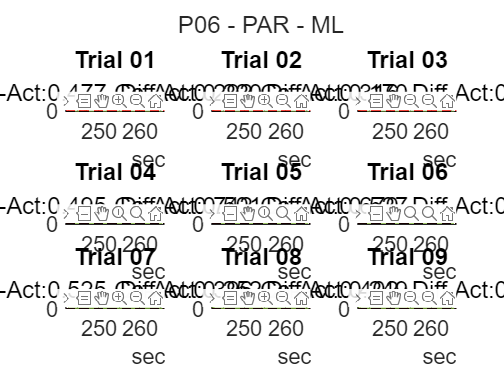

function [fig_handle] = plot_bounded_fit(x, y, ax_handle, y_color)
y_fit = fit(x, y, 'poly1');
y_bounds = predint(y_fit, x, 0.95, 'functional', 'on');
x_conf = [x' flip(x')];
y_conf = [y_bounds(:,2)' flip(y_bounds(:,1)')];
hold on
rgb_color = convertStringsToChars(y_color);
rgb_color = reshape(sscanf(rgb_color(2:end), '%2x') / 255, [], 3);
p = fill(ax_handle, x_conf, y_conf, rgb_color);
p.FaceColor = [rgb_color];

p.FaceAlpha = 0.5;
p.EdgeColor = 'none';
plot(ax_handle, x, y_bounds, '--', 'Color',y_color); xlim ([0 10]); ylim([0 0.8]);

thresholded_se = 100×5 logical array
   1   1   1   1   0
   0   1   1   0   1
   1   0   0   1   1
   1   0   1   1   1
   0   1   0   1   1
   0   1   0   0   1
   0   1   1   0   0
   1   0   1   0   1
   0   0   1   1   1
   0   1   1   1   1


fs = 30.3030

max_h =      5     6     6     6     5


max_h =     0.1650    0.1980    0.1980    0.1980    0.1650


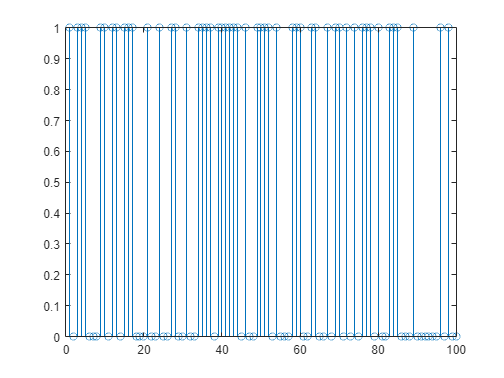

plot(ax_handle, x, [y, feval(y_fit, x)], 'Color', y_color);
hold off

end




Super loop